format long
clearvars all

# Oppgave 1

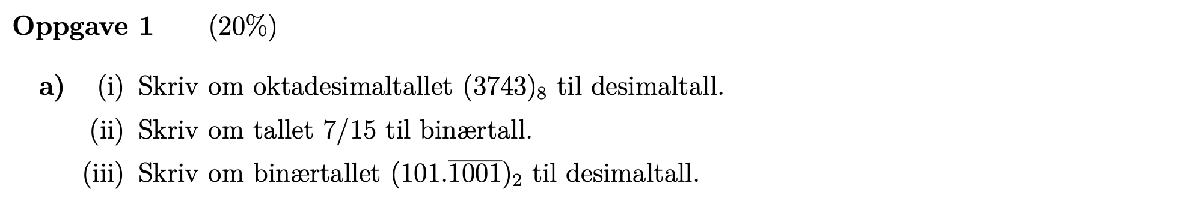

#### (i)


$${3743}_8 =\left(3*8^3 \right)+\left(7*8^2 \right)+\left(4*8^1 \right)+\left(3*8^0 \right)=2019$$


(3*8^3)+(7*8^2)+(4*8)+(3*8^0)

ans =         2019


#### (ii)


$$\begin{array}{l}
2*\frac{7}{15}=\frac{14}{15}+0\\
2*\frac{14}{15}=\frac{13}{15}+1\\
2*\frac{13}{15}=\frac{11}{15}+1\\
2*\frac{11}{15}=\frac{7}{15}+1
\end{array}$$
           
$${\frac{7}{15}}_{10} =0\ldotp {\overline{0111} }_2$$


#### (iii)

heltallsdel: $4+1=5$

desimaldel:

 
$$\begin{array}{l}
x=0\ldotp 100110011001\ldotp \ldotp_2 \\
2^4 x=1001\ldotp 10011001\ldotp \ldotp \ldotp_2 \\
2^4 x-x={1001}_2 \\
16x-x=8+1\\
15x=9\\
x=\frac{9}{15}=\frac{3}{5}
\end{array}$$



$$101\ldotp {\overline{1001} }_2 =5+\frac{3}{5}=\frac{28}{5}=5\ldotp 6$$


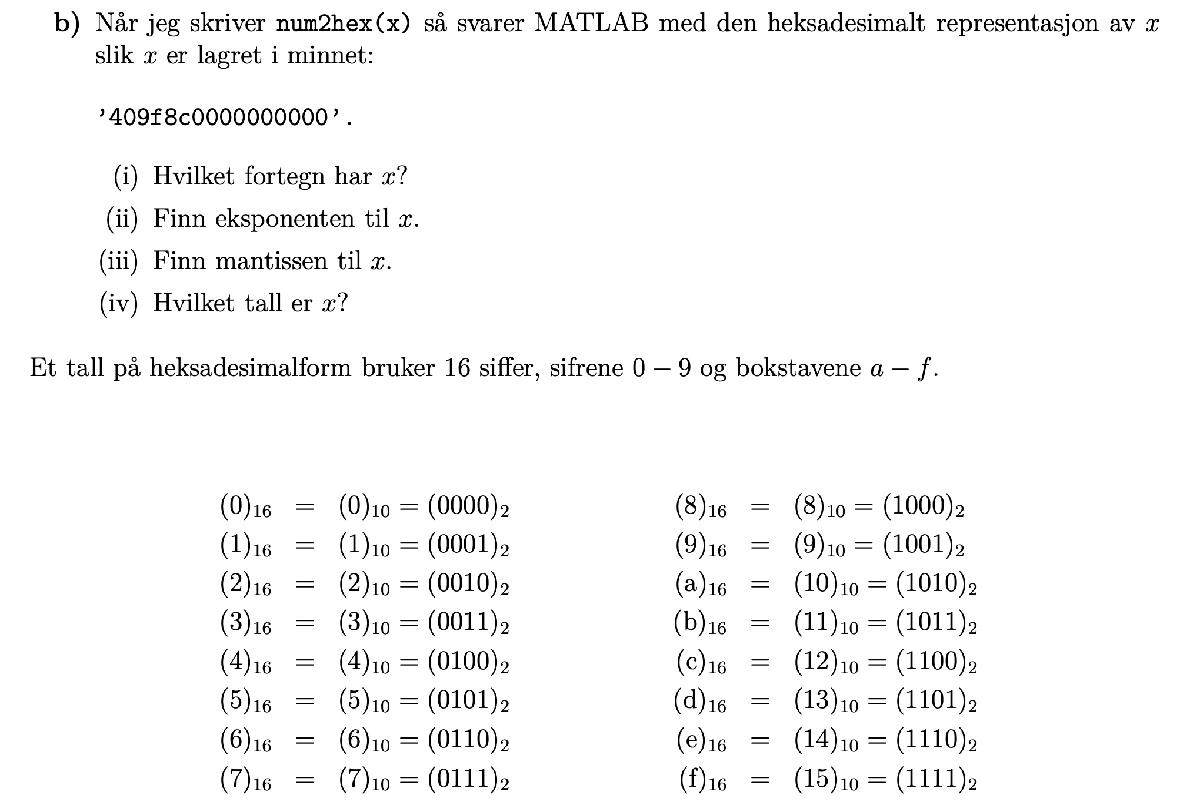

skriver om til binær:


$$409{\mathrm{f8c0000000000}}_{16} =0100\;0000\;1001\;1111\;1000\;1100\;0000\;0000\;0000\;0000\;0000\;0000\;0000\;0000\;0000\;0000$$


bits = 16*4;
s_bits = 1;
e_bits = 11;
m_bits = bits-s_bits-e_bits;

#### (i)

finner første bit: $4_{16} ={0100}_2$ første bit er 0 og tallet er positivt:

s = 0;

#### (ii)

matlab bruker 11 bit for eksponenten, de neste 11 bit etter s er da eksponenten:


$${10000001001}_2 =2^{10} +2^3 +2^0$$


e = 2^10+2^3+2^0

e =         1033


eksponentbias = 2^10-1;
e_eff = e-eksponentbias

e_eff =     10


#### (iii)

resten av tallet er da mantissen (52 bits)


$${\mathrm{f8c0000000000}}_{16}$$



$$1111\;1000\;1100\;0000\;0000\;0000\;0000\;0000\;0000\;0000\;0000\;0000\;{0000}_2$$


m = 15*16^12+8*16^11+12*16^10

m =      4.376056278548480e+15


m_maks = 2^(52)

m_maks =      4.503599627370496e+15


m_eff = 1 + m/m_maks

m_eff =    1.971679687500000


#### (iv)


$$x={\left(-1\right)}^s *2^{e-\left(1023\right)} *\left(1+\frac{m}{2^{52} }\right)$$


x = (-1)^s * 2^(e-eksponentbias) * (1 + m/m_maks)

x =         2019


x = (-1)^s * 2^e_eff * m_eff;

# Oppgave 2

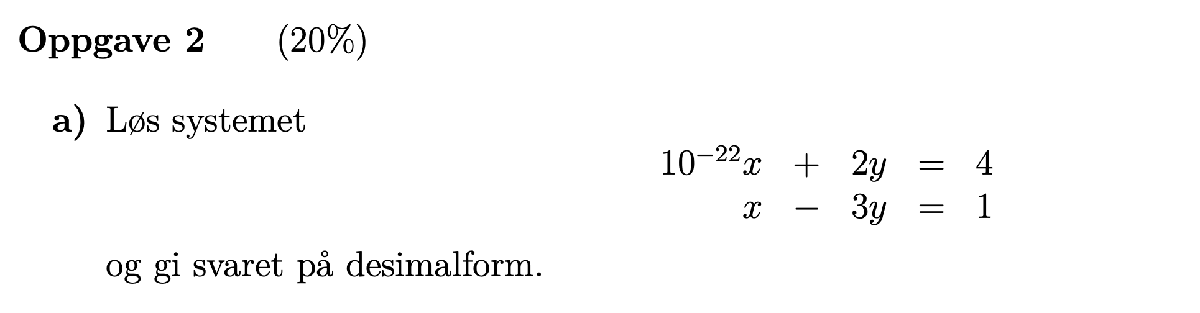

A = [10^-22  2 4; 
	      1 -3 1];

Vi vil unngå swamping, så vi bruker delvis pivotering

P = [0 1; 
	 1 0];
tilbakesubstitusjon(gausselim(P*A))

ans =      7
     2


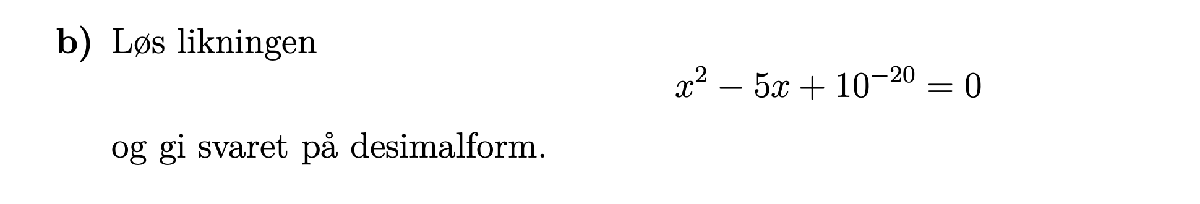


$$x=\frac{-b\pm \sqrt{b^2 -4\mathrm{ac}}}{2a}=\frac{5\pm \sqrt{5^2 -4*1*{10}^{-20} }}{2*1}=\frac{5\pm \sqrt{25-4*{10}^{-20} }}{2}$$


for å unngå swamping ganger vi med konjugatet:

x1 = (5+sqrt(25-4*10^-20))/2

x1 =      5



$$\begin{array}{l}
x_2 =\frac{5-\sqrt{25-4*{10}^{-20} }}{2}=\frac{\left(5-\sqrt{25-4*{10}^{-20} }\right)\left(5+\sqrt{25-4*{10}^{-20} }\right)}{2\left(5+\sqrt{25-4*{10}^{-20} }\right)}=\frac{5^2 -{\left(\sqrt{25-4*{10}^{-20} }\right)}^2 }{2\left(5+\sqrt{25-4*{10}^{-20} }\right)}=\frac{25-25+4*{10}^{-20} }{2*\left(10\right)}\\
\;\;\;\;=\frac{4*{10}^{-20} }{20}
\end{array}$$


x2 = (4*10^-20)/20

x2 =      2.000000000000000e-21


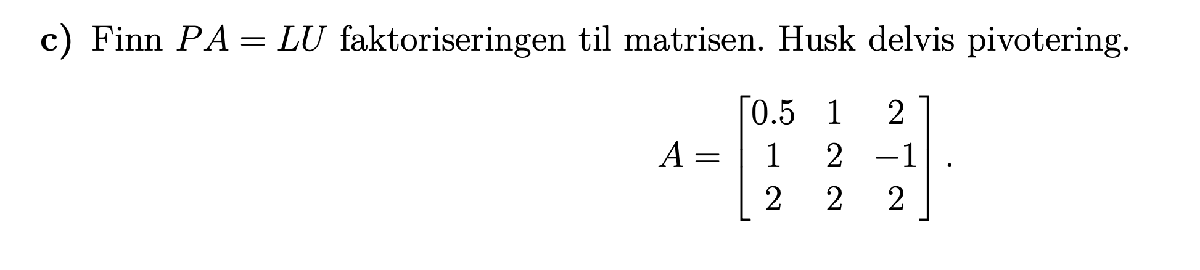


$$\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
2 & 2 & 2\\
1 & 2 & -1\\
1/2 & 1 & 2
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccc}
2 & 2 & 2\\
1/2 & 1 & -2\\
1/4 & 1/2 & 3/2
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccc}
2 & 2 & 2\\
1/2 & 1 & -2\\
1/4 & 1/2 & 5/2
\end{array}\right\rbrack$$


      P                    A                          L                    U


$$\left\lbrack \begin{array}{ccc}
0 & 0 & 1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1/2 & 1 & 2\\
1 & 2 & -1\\
2 & 2 & 2
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
1/2 & 1 & 0\\
1/4 & 1/2 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
2 & 2 & 2\\
0 & 1 & -2\\
0 & 0 & 5/2
\end{array}\right\rbrack$$


# Oppgave 3

# Oppgave 4

#### a)

A = [-3 0 2;
	 0 -1 2;
	 2 2 -2];
x_0 = [1;
	   0;
	   0];
i = power_iteration(A, x_0, 5)

i =   -4.998031371420348


ii = power_iteration_inverse(A, x_0, 0, 5)

ii =    1.023634480784546


iii = power_iteration_inverse(A, x_0, 3, 5)

iii =    0.996766159537612


iv = power_iteration_inverse(A, x_0, -3, 5)

iv =   -1.994126297503461


#### b)

Potensiteriasjon:


$$x_0 =\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack$$



$$u_0 =x_0 *\frac{1}{\left|x_0 \right|}=\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack *\frac{1}{\sqrt{1^2 +0^2 +0^2 }}=\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack$$



$$x_1 ={A*u}_0 =\left\lbrack \begin{array}{ccc}
-3 & 0 & 2\\
0 & -1 & 2\\
2 & 2 & -2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
2\\
-2
\end{array}\right\rbrack$$
    


$$u_1 =x_1 *\frac{1}{\left|x_1 \right|}=\left\lbrack \begin{array}{c}
2\\
2\\
-2
\end{array}\right\rbrack *\frac{1}{\sqrt{2^2 +2^2 +2^2 }}=\frac{1}{\sqrt{12}}\left\lbrack \begin{array}{c}
2\\
2\\
-2
\end{array}\right\rbrack =\frac{\sqrt{3}}{3}\left\lbrack \begin{array}{c}
1\\
1\\
-1
\end{array}\right\rbrack$$



$$x_2 =A*u_1 =\left\lbrack \begin{array}{ccc}
-3 & 0 & 2\\
0 & -1 & 2\\
2 & 2 & -2
\end{array}\right\rbrack \frac{\sqrt{3}}{3}\left\lbrack \begin{array}{c}
1\\
1\\
-1
\end{array}\right\rbrack =\frac{\sqrt{3}}{3}\left\lbrack \begin{array}{c}
-5\\
-3\\
6
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-2\ldotp 887\\
-1\ldotp 732\\
3\ldotp 464
\end{array}\right\rbrack$$


x2 = sqrt(3)/(3) * [-5 -3 6]'

x2 =   -2.886751345948129
  -1.732050807568877
   3.464101615137754



$$u_2 =x_2 *\frac{1}{\left|x_2 \right|}=\frac{\sqrt{3}}{3}\left\lbrack \begin{array}{c}
-5\\
-3\\
6
\end{array}\right\rbrack *\frac{1}{\sqrt{5^2 +3^2 +6^2 }}=\frac{\sqrt{3}}{3\sqrt{70}}\left\lbrack \begin{array}{c}
-5\\
-3\\
6
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-0\ldotp 345\\
-0\ldotp 207\\
0\ldotp 414
\end{array}\right\rbrack$$


u2 = sqrt(3)/(3*sqrt(70)) * [-5 -3 6]'

u2 =   -0.345032779671177
  -0.207019667802706
   0.414039335605413


#### c)


$$\begin{array}{l}
A=\left\lbrack \begin{array}{ccc}
-3 & 0 & 2\\
0 & -1 & 2\\
2 & 2 & -2
\end{array}\right\rbrack \\
x_0 =\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack 
\end{array}$$



$$u_0 =x_0 /\left|\left|x_0 \right|\right|=\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack /\sqrt[2]{1^2 +0^2 +0^2 }=\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack /1=\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack$$



$$\lambda_0 =u_0^T *{\mathrm{Au}}_0 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack *\left\lbrack \begin{array}{ccc}
-3 & 0 & 2\\
0 & -1 & 2\\
2 & 2 & -2
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
-3\\
0\\
2
\end{array}\right\rbrack =-3$$


Svaret vil konvergere mot egenverdien -2, ettersom $\lambda_0 =-3$ havner nærmest denne egenverdien.

fortsetter:


$$A_s =\left(A-\lambda_0 I\right)=\left\lbrack \begin{array}{ccc}
-3 & 0 & 2\\
0 & -1 & 2\\
2 & 2 & -2
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
-3 & 0 & 0\\
0 & -3 & 0\\
0 & 0 & -3
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 0 & 2\\
0 & 2 & 2\\
2 & 2 & 1
\end{array}\right\rbrack$$


As_inv = inv([0 0 2; 0 2 2; 2 2 1])

As_inv =    0.250000000000000  -0.500000000000000   0.500000000000000
  -0.500000000000000   0.500000000000000                   0
   0.500000000000000                   0                   0



$$\begin{array}{l}
A_s^{-1} =\left\lbrack \begin{array}{cccccc}
0 & 0 & 2 & 1 & 0 & 0\\
0 & 2 & 2 & 0 & 1 & 0\\
2 & 2 & 1 & 0 & 0 & 1
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{cccccc}
2 & 2 & 1 & 0 & 0 & 1\\
0 & 2 & 2 & 0 & 1 & 0\\
0 & 0 & 2 & 1 & 0 & 0
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{cccccc}
1 & 1 & 1/2 & 0 & 0 & 1/2\\
0 & 1 & 1 & 0 & 1/2 & 0\\
0 & 0 & 1 & 1/2 & 0 & 0
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{cccccc}
1 & 0 & -1/2 & 0 & -1/2 & 1/2\\
0 & 1 & 1 & 0 & 1/2 & 0\\
0 & 0 & 1 & 1/2 & 0 & 0
\end{array}\right\rbrack \\
\Rightarrow \left\lbrack \begin{array}{cccccc}
1 & 0 & 0 & 1/4 & -1/2 & 1/2\\
0 & 1 & 0 & -1/2 & 1/2 & 0\\
0 & 0 & 1 & 1/2 & 0 & 0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1/4 & -1/2 & 1/2\\
-1/2 & 1/2 & 0\\
1/2 & 0 & 0
\end{array}\right\rbrack 
\end{array}$$



$$x_1 =A_s^{-1} u_0 ={\left\lbrack \begin{array}{ccc}
0 & 0 & 2\\
0 & 2 & 2\\
2 & 2 & 1
\end{array}\right\rbrack }^{-1} *\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1/4 & -1/2 & 1/2\\
-1/2 & 1/2 & 0\\
1/2 & 0 & 0
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1/4\\
-1/2\\
1/2
\end{array}\right\rbrack$$


[lambda_0 ,u_0, x_1] = RayleightQIter(A,x_0,1)

lambda_0 =     -3


u_0 =      1
     0
     0


x_1 =    0.250000000000000
  -0.500000000000000
   0.500000000000000


# Oppgave 5

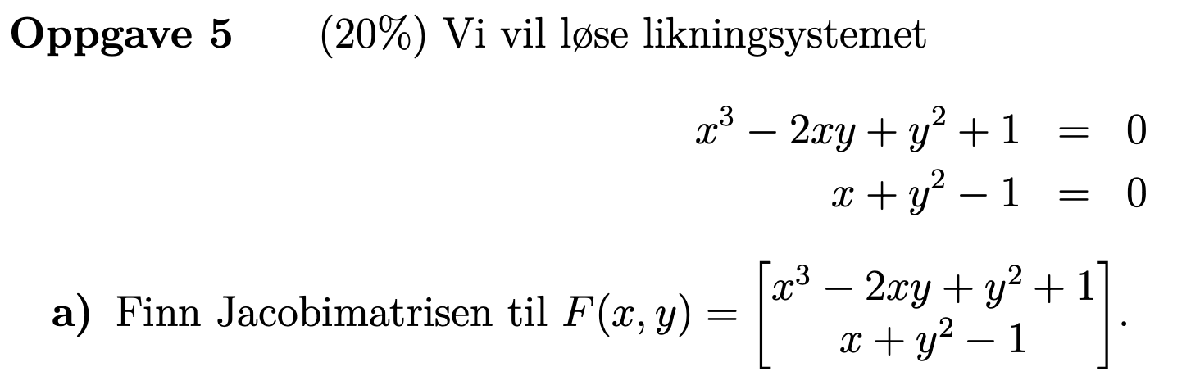


$$\mathrm{DF}=\left\lbrack \begin{array}{cc}
\frac{d}{\textrm{d}x}\left(x^3 -2\mathrm{xy}+y^2 +1\right) & \frac{d}{\textrm{d}y}\left(x^3 -2\mathrm{xy}+y^2 +1\right)\\
\frac{d}{\textrm{d}x}\left(x+y^2 -1\right) & \frac{d}{\textrm{d}y}\left(x+y^2 -1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
3x^2 -2y & -2x+2y\\
1 & 2y
\end{array}\right\rbrack$$


#### 


$$X_1 =X_0 -S$$



$$S={\mathrm{DF}\left(-1,-1\right)}^{-1} F\left(-1,-1\right)$$



$$\mathrm{DF}\left(-1,-1\right)=\left\lbrack \begin{array}{cc}
5 & 0\\
1 & -2
\end{array}\right\rbrack \Rightarrow {\mathrm{DF}\left(-1,-1\right)}^{-1} =\frac{1}{\left(5*-2\right)-\left(1*0\right)}\left\lbrack \begin{array}{cc}
-2 & 0\\
-1 & 5
\end{array}\right\rbrack =-\frac{1}{10}\left\lbrack \begin{array}{cc}
-2 & 0\\
-1 & 5
\end{array}\right\rbrack$$



$$F\left(-1,-1\right)=\left\lbrack \begin{array}{c}
-1\\
-1
\end{array}\right\rbrack$$



$$S=-\frac{1}{10}\left\lbrack \begin{array}{cc}
-2 & 0\\
-1 & 5
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
-1\\
-1
\end{array}\right\rbrack =-\frac{1}{10}\left\lbrack \begin{array}{c}
2\\
-4
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-1/5\\
2/5
\end{array}\right\rbrack$$



$$X_1 =X_0 -S=\left\lbrack \begin{array}{c}
-1\\
-1
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
-1/5\\
2/5
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-1+1/5\\
-1-2/5
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-4/5\\
-7/5
\end{array}\right\rbrack$$



$$\left(x_1 ,y_1 \right)=\left(-4/5,-7/5\right)$$
